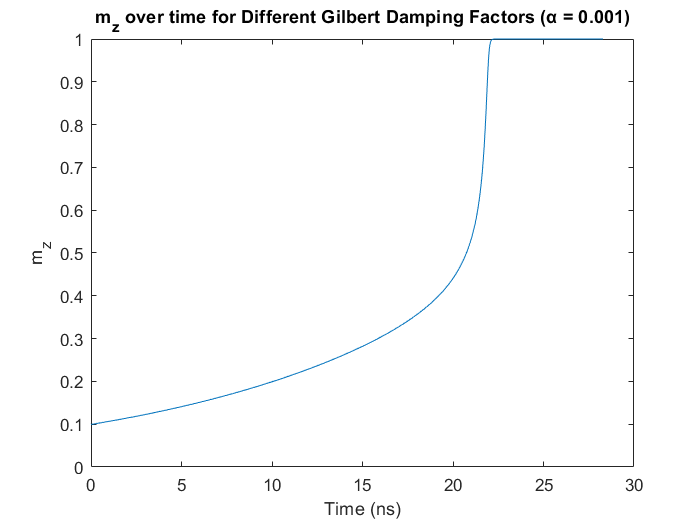

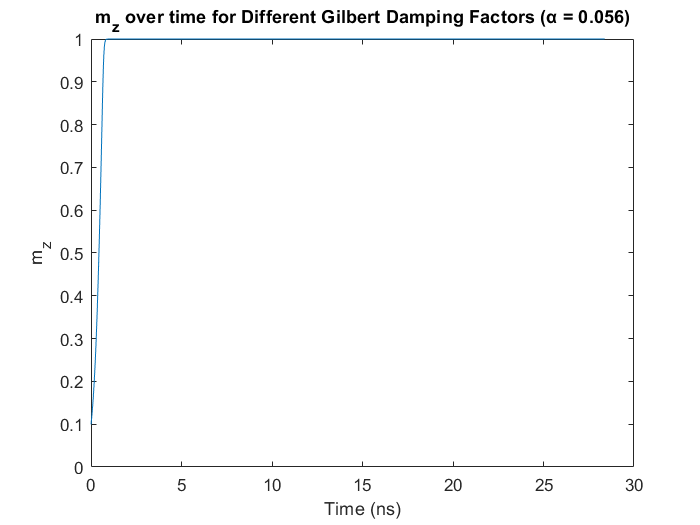

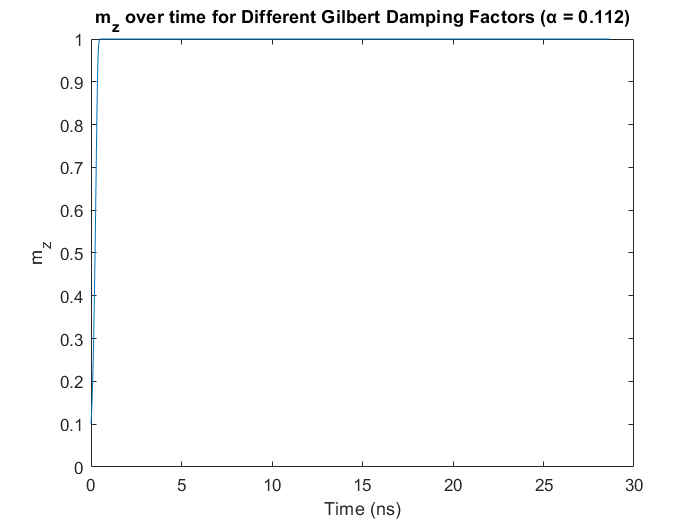

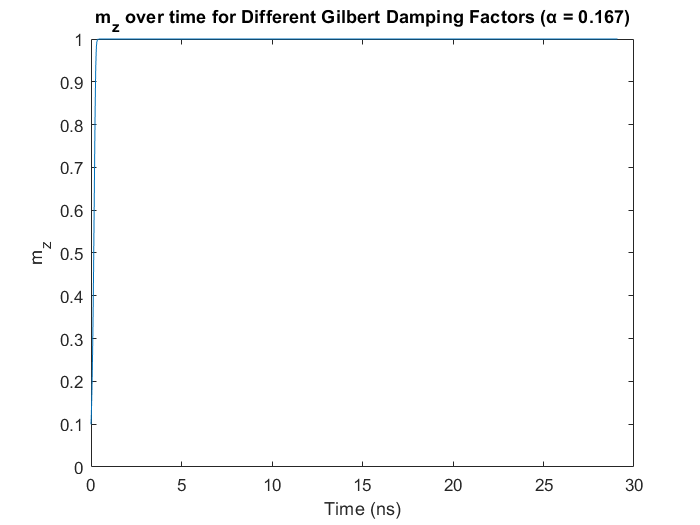

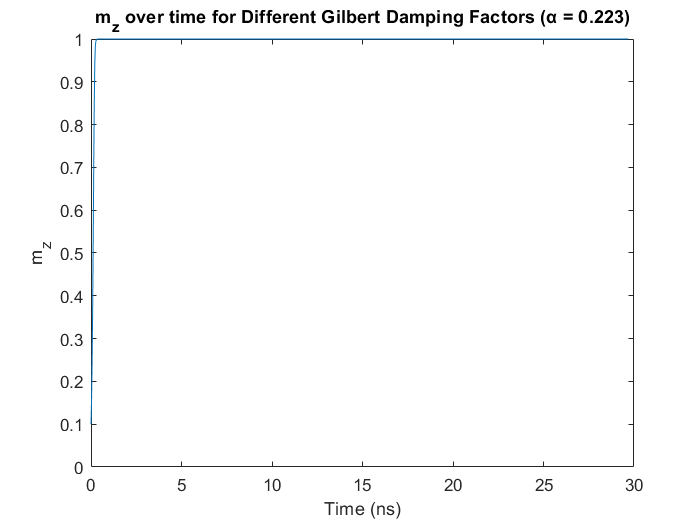

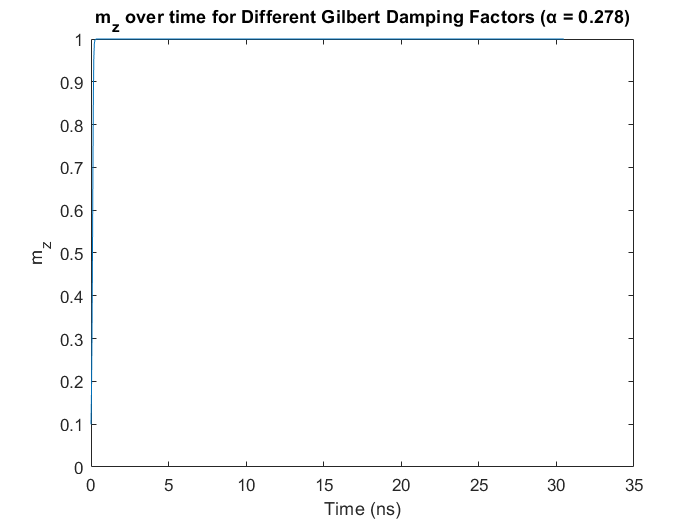

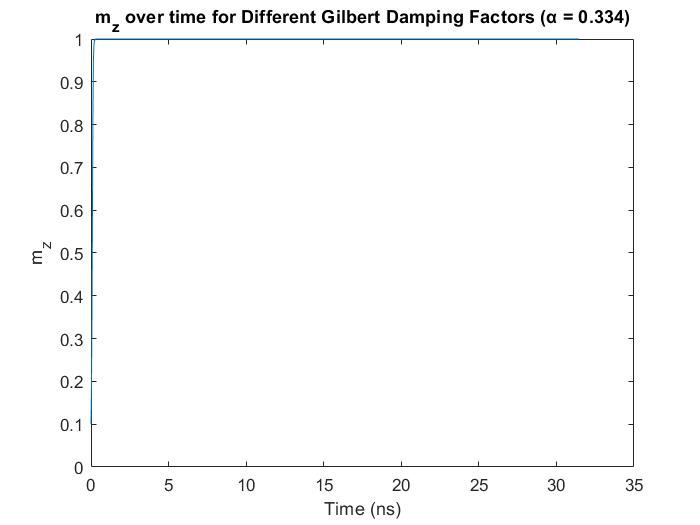

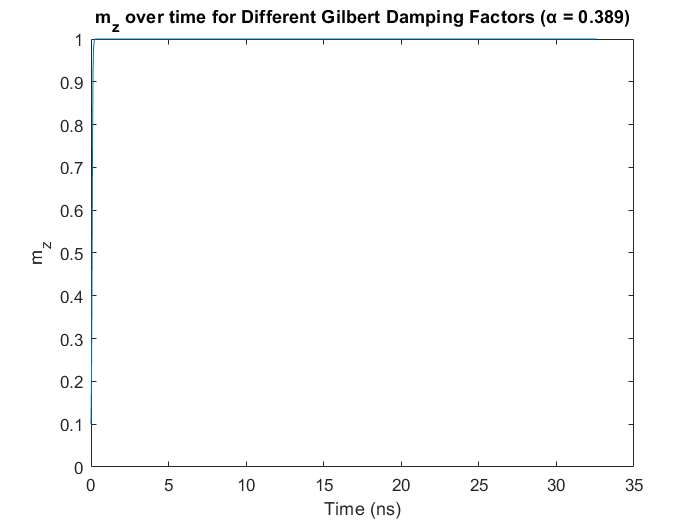

clc;
clear all;
close all;

gamma = 2.21276e5;  
mu = 1.2566e-6;    
h_k = 3.1951e5;    

tau1 = 0;
tau2 = 2000;
N = 1000;
h = (tau2 - tau1) / N;
tau = linspace(tau1, tau2, N+1);

n=input("how many values of alpha (atleast 10): ");

alphas = linspace(0.001, 0.5, n); 

relaxation_times = zeros(size(alphas)); 

m_initial = input("initial magnetization: ");
m_initial = m_initial/norm(m_initial); 

for j = 1:length(alphas)
    alpha = alphas(j); 
    
    m = zeros(N+1, 3);
    m(1, :) = m_initial;
   
    for i = 1:N
        k1 = h*llg(m(i, :), alpha);
        k2 = h*llg(m(i, :) + 0.5*k1, alpha);
        k3 = h*llg(m(i, :) + 0.5*k2, alpha);
        k4 = h*llg(m(i, :) + k3, alpha);
        
        m(i+1, :) = m(i, :) + (1/6) * (k1 + 2*k2 + 2*k3 + k4);
        m(i+1, :) = m(i+1, :) / norm(m(i+1, :)); 
    end
    
    time = tau * (1 + alpha.^2) / (gamma * h_k); 
    
    figure;
    plot(time * 1e9, m(:,3));
    xlabel('Time (ns)');
    ylabel('m_z');
    title(['m_z over time for Different Gilbert Damping Factors (α = ' num2str(alpha, '%.3f') ')']);
    
    rt = find(abs(m(:, 3)) >= 0.99, 1);
    if isempty(rt)
        relaxation_times(j) = NaN;
    else
        relaxation_times(j) = time(rt) * 1e9;
    end
end


disp(table(alphas', relaxation_times','VariableNames', {'Damping Factor (α)', 'Relaxation Time (ns)'}));

    Damping Factor (α)    Relaxation Time (ns)
    __________________    ____________________

            0.001                22.065       
         0.056444               0.76623       
          0.11189               0.45828       
          0.16733               0.31989       
          0.22278               0.26723       
          0.27822               0.24383       
          0.33367               0.22007       
          0.38911               0.19543       
          0.44456               0.20328       
              0.5               0.21216       



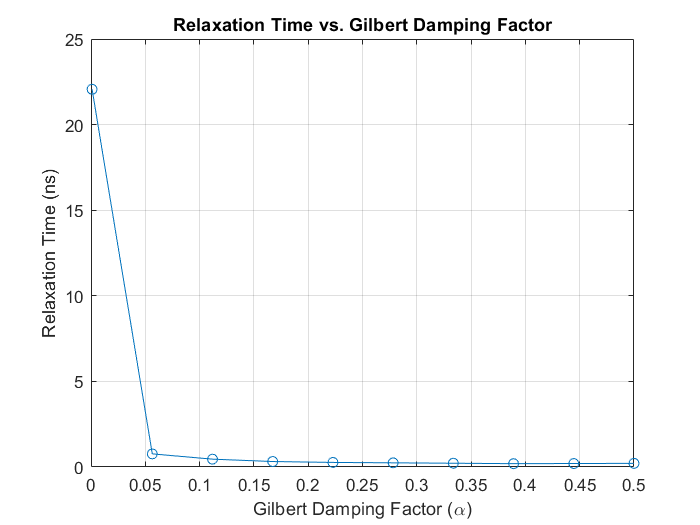


figure;
plot(alphas, relaxation_times, 'o-');
xlabel('Gilbert Damping Factor (\alpha)');
ylabel('Relaxation Time (ns)');
title('Relaxation Time vs. Gilbert Damping Factor');
grid on;

function llg = llg(m, alpha)
    H = [0, 0, m(3)]; 
    dynamic = cross(m, H);
    damping = cross(m, dynamic);
    llg = -dynamic - alpha * damping;
end

